Processing file Mixer_spectrum_2Ghz_0dbm_100Mhz_0dbm.csv...


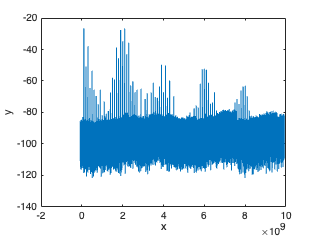

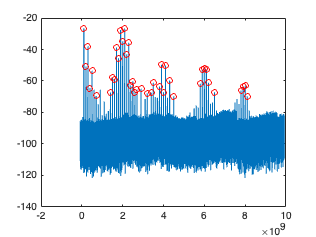

peak_table = 50×2 table
    x coor peak    y coor peak
    ___________    ___________

        1e+08        -26.736  
        2e+08        -50.781  
        3e+08        -37.857  
        4e+08        -64.446  
        5e+08        -53.498  
        7e+08        -69.492  
      1.1e+09         -73.02  
      1.4e+09        -67.241  
      1.5e+09        -57.981  
      1.6e+09        -58.975  
      1.7e+09        -38.713  
      1.8e+09        -45.625  
      1.9e+09        -27.641  
        2e+09        -34.726  
      2.1e+09        -26.587  
      2.2e+09        -43.036  


Processing file Mixer_spectrum_2Ghz_0dbm_27Mhz_0dbm.csv...


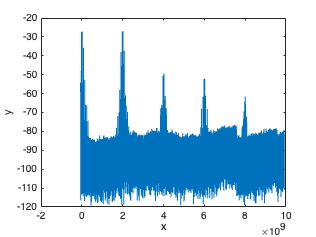

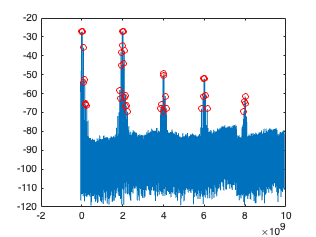

peak_table = 50×2 table
    x coor peak    y coor peak
    ___________    ___________

       -2e+07        -27.306  
        2e+07        -27.233  
        6e+07        -54.208  
        8e+07        -35.723  
      1.4e+08        -52.682  
      1.6e+08         -65.46  
      1.8e+08        -65.995  
      2.2e+08        -74.938  
      2.4e+08        -66.322  
        3e+08        -74.407  
     1.76e+09         -71.85  
     1.82e+09        -69.874  
     1.84e+09        -69.749  
     1.86e+09        -58.138  
      1.9e+09        -62.808  
     1.92e+09        -37.992  


Processing file Mixer_spectrum_2Ghz_0dbm_70Mhz_0dbm.csv...


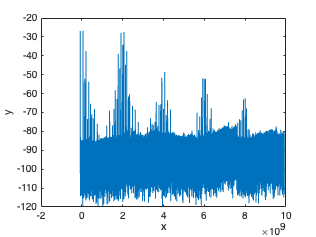

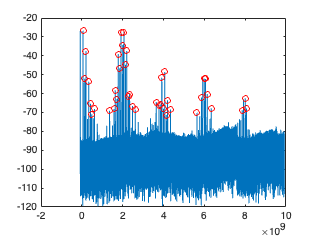

peak_table = 50×2 table
    x coor peak    y coor peak
    ___________    ___________

        6e+07        -26.756  
      1.4e+08        -52.099  
        2e+08        -37.524  
      2.8e+08        -73.424  
      3.4e+08         -53.67  
      4.2e+08        -65.409  
      4.8e+08        -70.967  
      5.6e+08        -73.094  
      6.2e+08        -68.088  
     1.36e+09        -69.108  
     1.58e+09        -68.136  
     1.64e+09        -58.263  
     1.72e+09        -62.863  
     1.78e+09        -39.109  
     1.86e+09        -46.649  
     1.92e+09        -27.752  


Processing file Mixer_spectrum_2Ghz_0dbm_95Mhz_0dbm.csv...


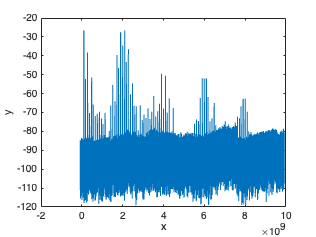

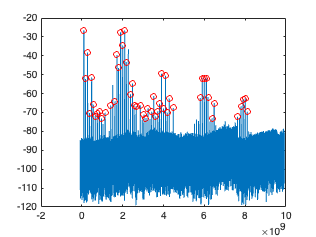

peak_table = 55×2 table
    x coor peak    y coor peak
    ___________    ___________

        1e+08        -26.655  
      1.8e+08         -52.27  
      2.8e+08        -38.215  
      3.8e+08        -70.284  
      4.8e+08        -51.478  
      5.6e+08        -65.703  
      6.6e+08        -71.882  
      7.6e+08        -70.637  
      8.6e+08        -69.658  
      9.6e+08        -73.173  
     1.14e+09        -70.143  
     1.42e+09        -66.231  
     1.62e+09        -64.083  
     1.72e+09        -39.533  
      1.8e+09        -46.448  
      1.9e+09        -27.501  


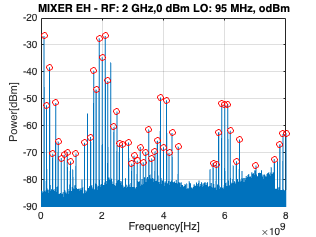

% Define the directory containing the CSV files
directory = '/Users/ohadformanair/Downloads/mixer_folder/MIXER_LOOP_RF_FREQ';

% Get a list of all the CSV files in the directory
file_list = dir(fullfile(directory, '*.csv'));

% Loop over each file in the directory
for i = 1:length(file_list)
    % Get the filename
    filename = file_list(i).name;
    
    % Display the name of the file being processed
    fprintf('Processing file %s...\n', filename);
    
    % Call the Peaks_find function on the current file
    Peaks_find(directory, filename);
end

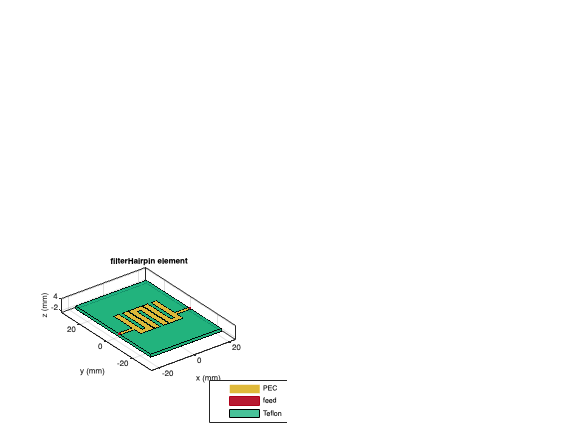

N = 3;
Ripple = 0.1;
BandWidth = 20;
Z0 = 50;
f = linspace(1.5e9,6e9,51);
EpsilonR = 2.1;
Height = 9.5e-3;
filter = filterHairpin;
filter.ResonatorOffset = [0e-3 0e-3 0e-3];
filter.Resonator(1).Length(1) = 20.4e-3;
filter.Resonator(1).Length(2) = 2e-3;
filter.Resonator(1).Length(3) = 20.4e-3;
filter.Spacing = [0.4e-3 0.4e-3];
filter.PortLineWidth = 1.85e-3;
filter.FeedOffset = [-4.565e-3 -4.565e-3];
figure;
show(filter);
view(-37,29);

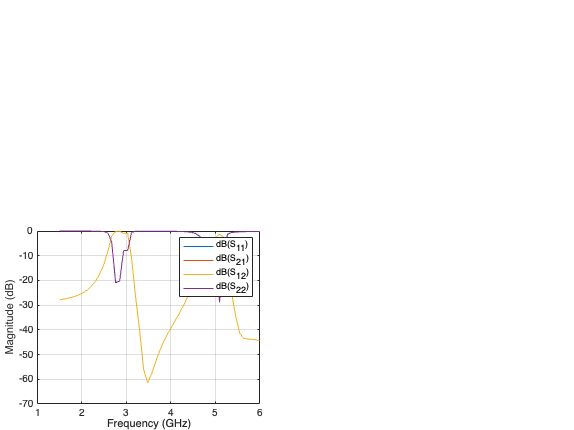


spar = sparameters(filter,f);
figure;
rfplot(spar);

eps_r = 2.1;
Z_c = 15;
A = Z_c/60*((eps_r+1)/(2))^0.5+(eps_r-1)/(eps_r+1)*(0.23+0.11/eps_r);
W_h = 8*exp(A)/(exp(2*A)-2)

W_h = 43.5685